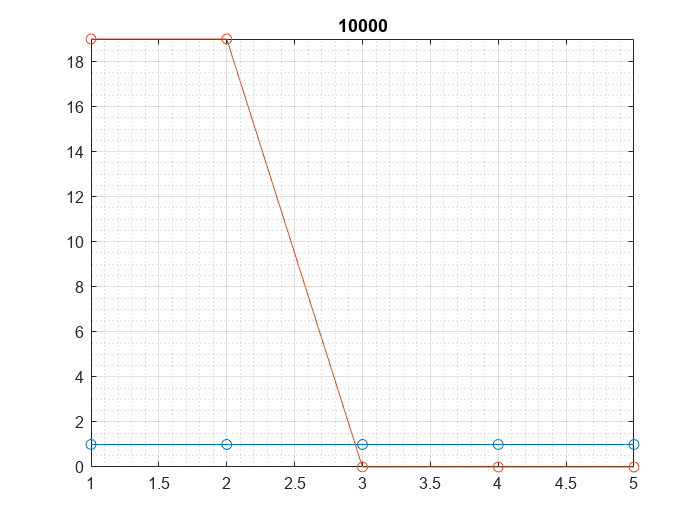

N = 5;			%	Maximum length of optical path
Na = 3;		%	Location of beamsplitter
Nb = 2;		%	Length of cycle
r1 = .9i;
t1 = sqrt(1-abs2(r1));
dphi1 = -pi/2;

M = sparse(2*N, 2*N);
M(1) = 1;											%	Constant input
M((2:N)+(0:N-2)*(2*N)) = 1;							%	Beam 1 - update from previous point
M(Na, [Na-1 N+Nb]) = [r1 t1];		%	Beam 1 - update @ BS
M(N+(2:Nb)+2*N*(N+(0:Nb-2))) = 1;					%	Beam 2 - update from previous point
M(N+Nb, :) = exp(1i*dphi1)*M(N+Nb, :);
M(N+1, [Na-1 N+Nb]) = [t1 r1];		%	Beam 2 - update @ BS

E = zeros(2*N, 1);
E(1) = 1;

for n = 1:10000
% 	if n==500
% 		E(1) = 0;
% 	end
	E = M*E;
	plot(abs2(reshape(E, [], 2)), "o-");
	axis tight;
	grid on;
	grid minor;
	title(n);
	drawnow;
end